## **Walkthrough of pseudotime analysis of interfollicular epidermal cells in UW sample using scEpath**

**Suoqin Jin**

**Dec 28, 2019**

### Install scEpath package

Please download the MATLAB package of scEpath from https://github.com/sqjin/scEpath, and then add path into the MATLAB workspace as follows.

clc; clear
path_codes = '/Users/suoqinjin/Google Drive/projects/project4_Dai/revisionR1/codes_submit/scEpath-master/';
addpath(genpath(path_codes))

### Run analysis

#### step 1: load data and cell attributes (such as cell type, sample id)

% Note: for the .txt files saved from R, please add a TAB sapce at the top-left corner of the file
T = readtable('rawData_UW_IFE.txt', 'Delimiter','\t','ReadRowNames',true,'ReadVariableNames',true);

iniData.genes = T.Properties.RowNames;iniData.barcodes = T.Properties.VariableNames;
iniData.data = sparse(table2array(T));
% iniData is a struct including three fields: data, genes, cells
% iniData.data: n x m data matrix (rows are genes and columns are cells)
% iniData.genes: n x 1 cell array contains the gene names
% iniData.cells: a table, rownames are cell barcodes and each column contains cell attributes (such as cell type, culture condition, day captured). The order shoule be the same with the columns of data matrix
% load the cell group information
meta = readtable('clusters_UW_IFE.txt', 'Delimiter','\t','ReadRowNames',true,'ReadVariableNames',1);
identity.group = meta{:,1};
iniData.cells = meta;

#### step 2: do preprocessing

minCells = 0; minGenes = 0;
proData = preprocessing(iniData, minCells, minGenes);
%   proData: a struct variable (store the data after QC) contains the same fields with iniData

#### step 3: construct a gene-gene co-expression network

ans = 'When tau is 0.10, the number of nodes is 14502.'

ans = 'When tau is 0.20, the number of nodes is 7341.'

ans = 'When tau is 0.30, the number of nodes is 2647.'

ans = 'When tau is 0.40, the number of nodes is 1123.'

ans = 'When tau is 0.50, the number of nodes is 273.'

ans = 'When tau is 0.60, the number of nodes is 119.'

ans = 'When tau is 0.70, the number of nodes is 52.'

ans = 'When tau is 0.80, the number of nodes is 14.'

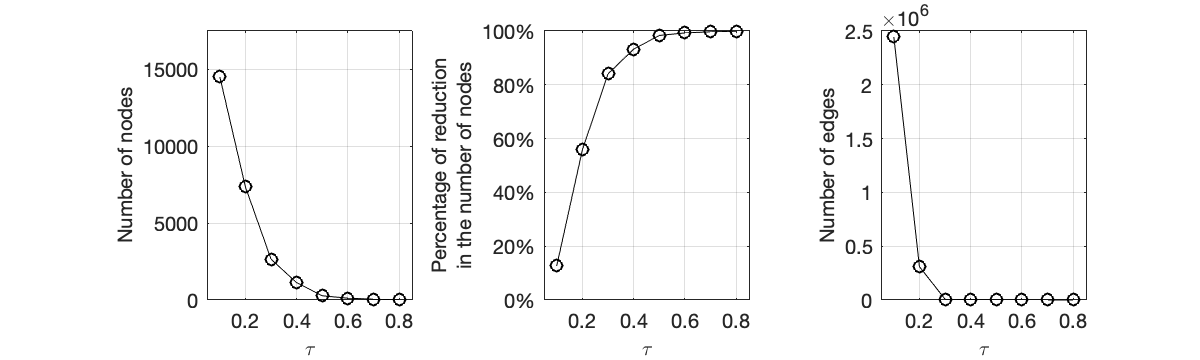

% by default: the network will be constructed by choosing the highest threshold without a significant reduction in the total number of genes;
% if one would like to quickly construct a network using a given threshold,then set quick_construct = 1 and give a tau (e.g.0.4);
quick_construct = 0; tau = [];
networkIfo = constructingNetwork(proData.data',quick_construct,tau); % a struct variable

% networkIfo.R: adjacency matrix (upper matrix) of the constructed network
% networkIfo.IDselect: the index of selected genes in the constructed network

####  step 4: estimate the single cell energy (scEnergy) for each cell

[scE,scEcell] = estimatingscEnergy(proData.data,networkIfo);
% scE: energy matrix, the same dimension with data
% scEcell; scEnergy of each cell

#### step 5: perform dimension reduction

% load the reduced UMAP space from Seurat
T = readtable('projectedData_ump_UW_IFE.txt', 'Delimiter','\t','ReadRowNames',1,'ReadVariableNames',1);
ydata = T{:,1:2};

#### step 6: perform unsupervised clustering

y = identity.group; groupUniNames = unique(y,'stable')

groupUniNames = 6×1 cell array
    {'Col17a1Hi'}
    {'ER'       }
    {'GA'       }
    {'Prolif'   }
    {'SP1'      }
    {'SP2'      }


clusterIfo = addClusterInfo(y,groupUniNames);% user can also add external clustering results here. y can be either a numerical or cell array.
% clusterIfo.identity: the updated cluster label of each cell
% clusterIfo.idxCluster: a cell array, each cell contains the index of cells belong to the each cluster
rootNode = 1;
numCluster = length(unique(clusterIfo.identity));

#### step 7: infer the cell lineage hierarchy

alpha = 0.01; theta1 = 0.8; % default parameters (see functions for details):
lineageIfo = inferingLineage(scEcell,ydata,clusterIfo,rootNode,alpha,theta1);
% lineageIfo.TP: transition probability TP
% lineageIfo.MDST: minimal directed spanning tree, i.e.,the inferred lineage
% lineageIfo.path: the node in each path
% lineageIfo.PDG: the constructed probabilistic directed graph
% lineageIfo.centroid: the centroid of each core cell


### Plotting

% visualization of results including clustering, cell lineage hierarchy, scEnergy comparison
% colors used in the final manuscript
colorCell = [255 22 34;0 185 56; 54 87 223;96 58 145; 242 148 3; 227 190 0]/255;

#### Visualize cells on two-dimensional space

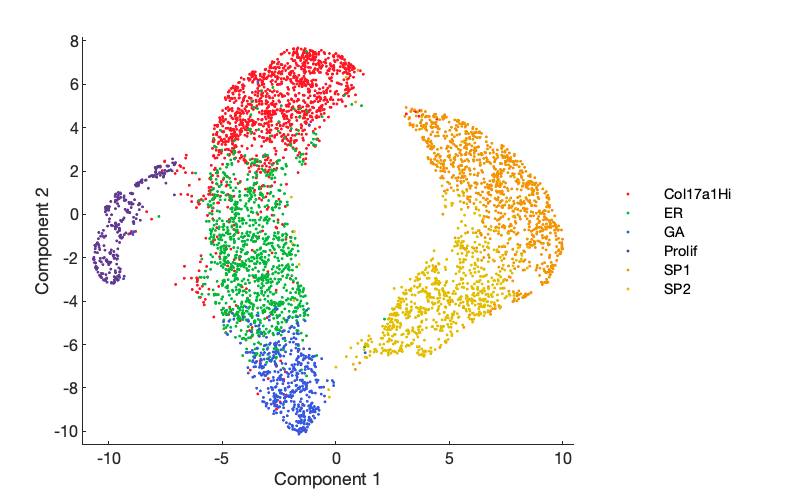

fig_width = 400; fig_height = 250;
figure('position', [600, 200, fig_width, fig_height])
gscatter(ydata(:,1),ydata(:,2),clusterIfo.identity,colorCell,[],4);box off
set(gca,'FontSize',8)
xlabel('Component 1','FontSize',10,'FontName','Arial');
ylabel('Component 2','FontSize',10,'FontName','Arial');
axis([min(ydata(:,1))-0.5 max(ydata(:,1))+0.5, min(ydata(:,2))-0.5 max(ydata(:,2))+0.5])
box off
[h,h2] = legend(groupUniNames,'Interpreter','none','Location','eastoutside','Box','off');
for i = 1:size(colorCell,1)
    h2(i).FontSize = 10;
end
for k = i+2:2:size(colorCell,1)*3
    h2(k).MarkerSize = 25;
end

#### Show the inferred cell lineage hierarchy with transition probability

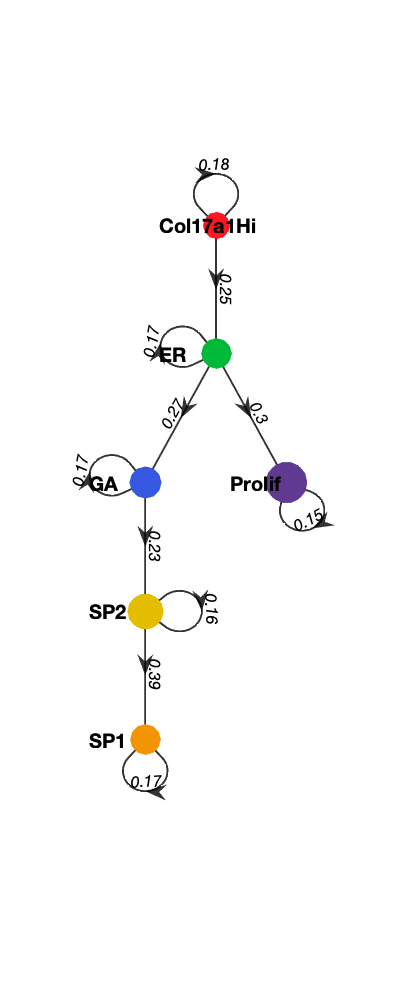

node_size = grpstats(full(scEcell),clusterIfo.identity,'median')*30; % the size of tree node, propotational to the median scEnergy of each cluster
showLoops = 1; fig_width = 200;
lineage_visualization(lineageIfo,groupUniNames,node_size,colorCell,showLoops,fig_width)

#### Show the scEnergy distribution in the low-dimensional space

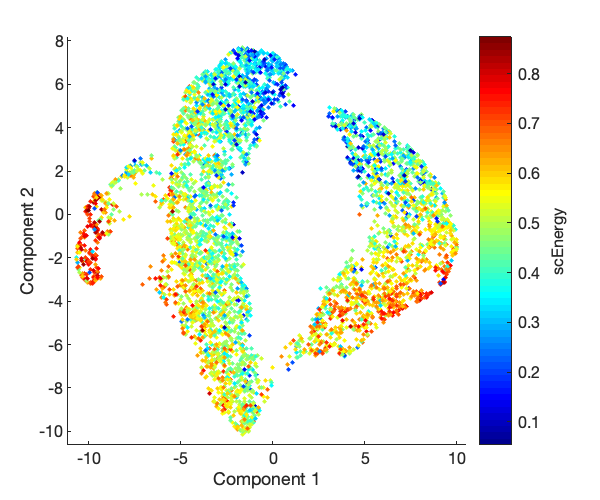

embedding = [ydata(:,1),ydata(:,2)];
fig_width = 300; fig_height = 250;
figure('position', [600, 200, fig_width, fig_height])
clf
color = scEcell;
pointsize = 6;
scatter(embedding(:,1), embedding(:,2), pointsize, color(:),'filled');
axis([min(ydata(:,1))-0.5 max(ydata(:,1))+0.5, min(ydata(:,2))-0.5 max(ydata(:,2))+0.5])
colormap(jet)
set(gca,'FontSize',8)
xlabel('Component 1','FontSize',10,'FontName','Arial');
ylabel('Component 2','FontSize',10,'FontName','Arial');
box off
c = colorbar;
c.Label.String = 'scEnergy';
c.Label.FontSize = 8;
c.FontSize = 8;

### Save all the variables in the workspace

save(fullfile('results','scEpath_pseudotime_UW_IFE.mat'));